data = [1, 98, -0.649;
2, 41, -0.645;
3, 53, -0.369;
4, 92, -0.485;
5, 100, 0.188;
6, 240, -0.036;
7, 976, -0.58;
8, 2499, 0.077;
9, 1420, 0.521;
10, 1382, 0.32;
11, 1017, 0.038;
12, 284, -0.696;
13, 181, -0.843;
14, 113, -0.779;
15, 87, -0.756;
16, 172, -0.522;
17, 510, -0.346;
18, 945, -0.228;
19, 2255, -0.159;
20, 4686, 0.467;
21, 5705, 1.367;
22, 4813, 1.082;
23, 2011, 0.171;
24, 427, -0.665;
25, 341, -0.886;
26, 251, -0.806;
27, 280, -0.505;
28, 321, -0.373;
29, 619, -0.246;
30, 1108, -0.349;
31, 2401, -0.5;
32, 3748, -0.212;
33, 6438, 0.608;
34, 8102, 0.942;
35, 4669, 0.394;
36, 1558, -0.57;
37, 1716, -0.683;
38, 1263, -0.662;
39, 1238, -0.28;
40, 1206, -0.35;
41, 1861, -0.078;
42, 2550, -0.09;
43, 3661, -0.257;
44, 7106, 0.101;
45, 11311, 1.145;
46, 13205, 3.366;
47, 5842, 1.661;
48, 1410, -0.243;
49, 1068, -0.683;
50, 935, -0.417;
51, 654, -0.539;
52, 934, -0.151;
53, 2059, -0.101;
54, 2974, 0.333;
55, 3564, -0.233;
56, 4673, -0.139;
57, 5298, 0.667;
58, 7324, 0.943;
59, 4650, 0.295;
60, 1470, -0.51;
61, 2507, -0.62;
62, 2221, -0.425;
63, 1961, -0.314;
64, 1977, -0.338;
65, 2414, 0.053;
66, 3674, -0.168;
67, 7831, -0.501;
68, 26101, 0.4;
69, 32571, 4.685;
70, 26547, 5.763;
71, 17601, 3.139;
72, 6640, 0.528;
73, 2986, -0.282;
74, 2256, -0.321;
75, 1745, -0.249;
76, 1937, -0.241;
77, 2276, 0.001;
78, 3138, -0.013;
79, 4241, 0.513;
80, 6619, 0.562;
81, 6235, 0.512;
82, 7041, 0.631;
83, 3937, 0.35;
84, 879, -0.494;
85, 389, -0.874;
86, 362, -0.802;
87, 453, -0.471;
88, 435, -0.571;
89, 625, -0.551;
90, 655, -0.597;
91, 1108, -0.671;
92, 2056, -0.499;
93, 3818, 0.104;
94, 5950, 0.404;
95, 4247, -0.058;
96, 1749, -0.763]

data = 1.0e+04 *

    0.0001    0.0098   -0.0001
    0.0002    0.0041   -0.0001
    0.0003    0.0053   -0.0000
    0.0004    0.0092   -0.0000
    0.0005    0.0100    0.0000
    0.0006    0.0240   -0.0000
    0.0007    0.0976   -0.0001
    0.0008    0.2499    0.0000
    0.0009    0.1420    0.0001
    0.0010    0.1382    0.0000



time = data(:,1)

time =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


cases = data(:,2)

cases =           98
          41
          53
          92
         100
         240
         976
        2499
        1420
        1382


searches = data(:,3)

searches =    -0.6490
   -0.6450
   -0.3690
   -0.4850
    0.1880
   -0.0360
   -0.5800
    0.0770
    0.5210
    0.3200


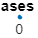

figure
scatter(time, cases, ".")

title("Dengue Cases over Time")
xlabel("Months")
ylabel("Cases")

% Assume the form y = mx + b
training_data = [searches(1:36,:), cases(1:36,:)]

training_data = 1.0e+03 *

   -0.0006    0.0980
   -0.0006    0.0410
   -0.0004    0.0530
   -0.0005    0.0920
    0.0002    0.1000
   -0.0000    0.2400
   -0.0006    0.9760
    0.0001    2.4990
    0.0005    1.4200
    0.0003    1.3820


A = [ones([36,1]), training_data(:,1)]

A =     1.0000   -0.6490
    1.0000   -0.6450
    1.0000   -0.3690
    1.0000   -0.4850
    1.0000    0.1880
    1.0000   -0.0360
    1.0000   -0.5800
    1.0000    0.0770
    1.0000    0.5210
    1.0000    0.3200


b = training_data(:,2)

b =           98
          41
          53
          92
         100
         240
         976
        2499
        1420
        1382



output = lsqr(A,b)

lsqr converged at iteration 2 to a solution with relative residual 0.46.


output = 1.0e+03 *

    2.1553
    2.9264


slope = output(2,:)

slope = 2.9264e+03

y_int = output(1,:)

y_int = 2.1553e+03

The column for number of searches is.. really weird. What does having -0.645 google searches even mean? I think this is why the approximation is giving very weird behavior, namely that at 0 searches, there are over 2000 cases.

x = linspace(-1,6)

x =    -1.0000   -0.9293   -0.8586   -0.7879   -0.7172   -0.6465   -0.5758   -0.5051   -0.4343   -0.3636   -0.2929   -0.2222   -0.1515   -0.0808   -0.0101    0.0606    0.1313    0.2020    0.2727    0.3434    0.4141    0.4848    0.5556    0.6263    0.6970    0.7677    0.8384    0.9091    0.9798    1.0505    1.1212    1.1919    1.2626    1.3333    1.4040    1.4747    1.5455    1.6162    1.6869    1.7576    1.8283    1.8990    1.9697    2.0404    2.1111    2.1818    2.2525    2.3232    2.3939    2.4646



y = (slope*x) + y_int

y = 1.0e+04 *

   -0.0771   -0.0564   -0.0357   -0.0150    0.0057    0.0263    0.0470    0.0677    0.0884    0.1091    0.1298    0.1505    0.1712    0.1919    0.2126    0.2333    0.2540    0.2746    0.2953    0.3160    0.3367    0.3574    0.3781    0.3988    0.4195    0.4402    0.4609    0.4816    0.5023    0.5229    0.5436    0.5643    0.5850    0.6057    0.6264    0.6471    0.6678    0.6885    0.7092    0.7299    0.7506    0.7712    0.7919    0.8126    0.8333    0.8540    0.8747    0.8954    0.9161    0.9368


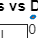


figure
scatter(searches(37:96,:), cases(37:96,:), ".")
title("Dengue Cases vs Dengues Searches")
xlabel("Searches")
ylabel("Cases")

hold on
plot(x,y)
legend("Cases", "Projected")

Ok, this actually fits better than I thought. I think somehow putting more weight on the data points corresponding to high #s of cases and searches would improve the fit. The peaks are short-lived, so there aren't many data points for them. This causes the fit to align more with the "uninteresting" lows.